Interface de texto para PVI

Autor:

  - Arménio Correia  .: armenioc@isec.pt

  - Ana Rita Conceição Pessoa - 2023112690 

  - João Francisco de Matos Claro - 2023112690 

Data : 13/03/2024

clear
% syms y(t)

strF="y+exp(3*t)";
%f=@(t,y) eval(vectorize(strF));
f=str2func(vectorize(strcat('@(t,y)', " ", strF)));
a = 0;
b = 1.5;
if ~(isscalar(b) && b > a)
    disp("Introduza um b > a");
end
n = 3;
if ~(isscalar(n) && n==floor(n) && n > 0)
    disp("Introduza um valor de n correto");
end
y0 = 2;

if(false)
    [t, y]=NEuler(f,a,b,n,y0);
    mostraAproximacoes("Euler",y);
    mostraGrafico("Euler", y, t);
end
if(false)
    [t, y]=NEulerMelhorado(f,a,b,n,y0);
    mostraAproximacoes("Euler Melhorado",y);
    mostraGrafico("Euler Melhorado", y, t);
end
if(false)
    [t, y]=RK2(f,a,b,n,y0);
    mostraAproximacoes("RK2",y);
    mostraGrafico("RK2", y, t);
end
if(false)
    [t, y]=RK4(f,a,b,n,y0);
    mostraAproximacoes("RK4",y);
    mostraGrafico("RK4", y, t);
end
if(true)
    [tode, y]=ode45(f, [a b], y0);
    mostraAproximacoes("ode45", y);
    mostraGrafico("ode45", y, tode);
    fprintf('\nPontos de aproximação da ode45\n');
    disp(table(tode));
end


Aproximações obtidas ode45:
      y   
    ______

         2
    2.1039
    2.2152
    2.3344
    2.4624
    2.6169
    2.7845
    2.9666
    3.1646
    3.3803
    3.6156
    3.8724
    4.1532
    4.4605
    4.7973
    5.1668
    5.5725
    6.0185
    6.5094
      7.05
    7.6461
    8.3038
    9.0303
    9.8331
    10.721
    11.704
    12.793
        14
    15.338
    16.824
    18.473
    20.305
    22.341
    24.605
    27.123
    29.925
    33.045
     36.52
     40.39
    44.703
    49.511
    50.056
    50.608
    51.166
    51.731




Pontos de aproximação da ode45


      tode  
    ________

           0
    0.033492
    0.066984
     0.10048
     0.13397
     0.17147
     0.20897
     0.24647
     0.28397
     0.32147
     0.35897
     0.39647
     0.43397
     0.47147
     0.50897
     0.54647
     0.58397
     0.62147
     0.65897
     0.69647
     0.73397
     0.77147
     0.80897
     0.84647
     0.88397
     0.92147
     0.95897
     0.99647
       1.034
      1.0715
       1.109
      1.1465
       1.184
      1.2215
       1.259
      1.2965
       1.334
      1.3715
       1.409
      1.4465
       1.484
       1.488
       1.492
       1.496
         1.5



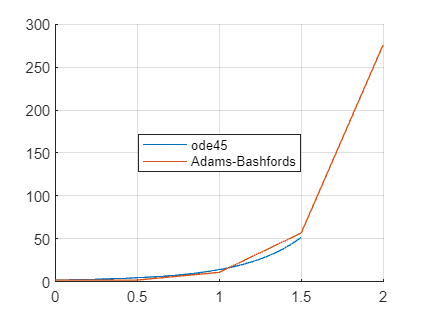


Aproximações obtidas Adams-Bashfords:
                        y                    
    _________________________________________

    2         2    10.973     56.81     276.3



if(true)
    [t, y]=AdamBashford(f,a,b,n,y0);
    mostraAproximacoes("Adams-Bashfords",y);
    mostraGrafico("Adams-Bashfords", y, t);
end

if(false)
    [t, y]=sExata(f,a,b,n,y0);
    mostraAproximacoes("Exata",y);
    mostraGrafico("Exata", y, t);
end
fprintf('\nPontos de aproximação \n');


Pontos de aproximação 


disp(table(t));

                  t              
    _____________________________

    0    0.5      1    1.5      2



%clear current plot holds
clf reset;

function mostraGrafico(metodo, y, t)

% fprintf('Deseja visualizar o grafico? (y,n)\n');
% ch=input('Opção: ', 's');
% if strcmp(ch,'y')
    hold on
    plot (t,y, 'DisplayName', metodo);
    legend('location', 'best');
    hold off
    grid on
% else
%     fprintf('\nIntroduza y ou n\n');
% end
end

function mostraAproximacoes(metodo, y)
fprintf('\nAproximações obtidas ' + metodo + ":\n");
disp(table(y));
end
